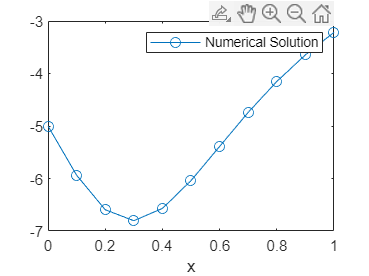

y0 = -5;
t0 = 0;
tn = 1;
h = 0.1;

result = Runge_Kutta4(@f, t0, y0, tn, h);
x = linspace(0, 1, length(result));
plot(x, result, '-o', 'DisplayName', 'Numerical Solution');

xlabel('x');
legend();

function res = Runge_Kutta4(f, t0, y0, tn, h)
    res = [y0];
    t = t0;
    for i = 1:floor((tn-t0)/h)
        k1 = f(t, res(end));
        k2 = f(t + h / 2, res(end) + h * k1 / 2);
        k3 = f(t + h / 2, res(end) + h * k2 / 2);
        k4 = f(t + h, res(end) + h * k3);
        y_next = res(end) + h*(k1 + 2 * k2 + 2 * k3 + k4)/6;
        res = [res, y_next];
        t = t + h;
    end
end

function y = f(x, y)
    y = x*y^2 + 2*y;
end